%Number 1
syms x;
%Got Help from MATLAB Online
%https://www.mathworks.com/matlabcentral/answers/75613-create-an-anonymous-function-after-symbolic-differentiation
f = @(x) (x^2) - 2;
df = diff(f(x));
if isempty(symvar(df))
  fPrime = str2func(['@(x) repmat(', char(df), ', size(x))'])
else
  fPrime = matlabFunction(df);
end
% newtones(f,fPrime,3,.005,50);
% Functions implemented below

%Number 2
% f = @(x) (x^2) - 2;
% secant(f,1,2,.005,10);
%Functions implemented below

%Number 3a
g1 = newtones(f,fPrime,3,eps(),10);
g2 = secant(f,1,2,eps(),10);

The procedure was successful, p is: 1.4142

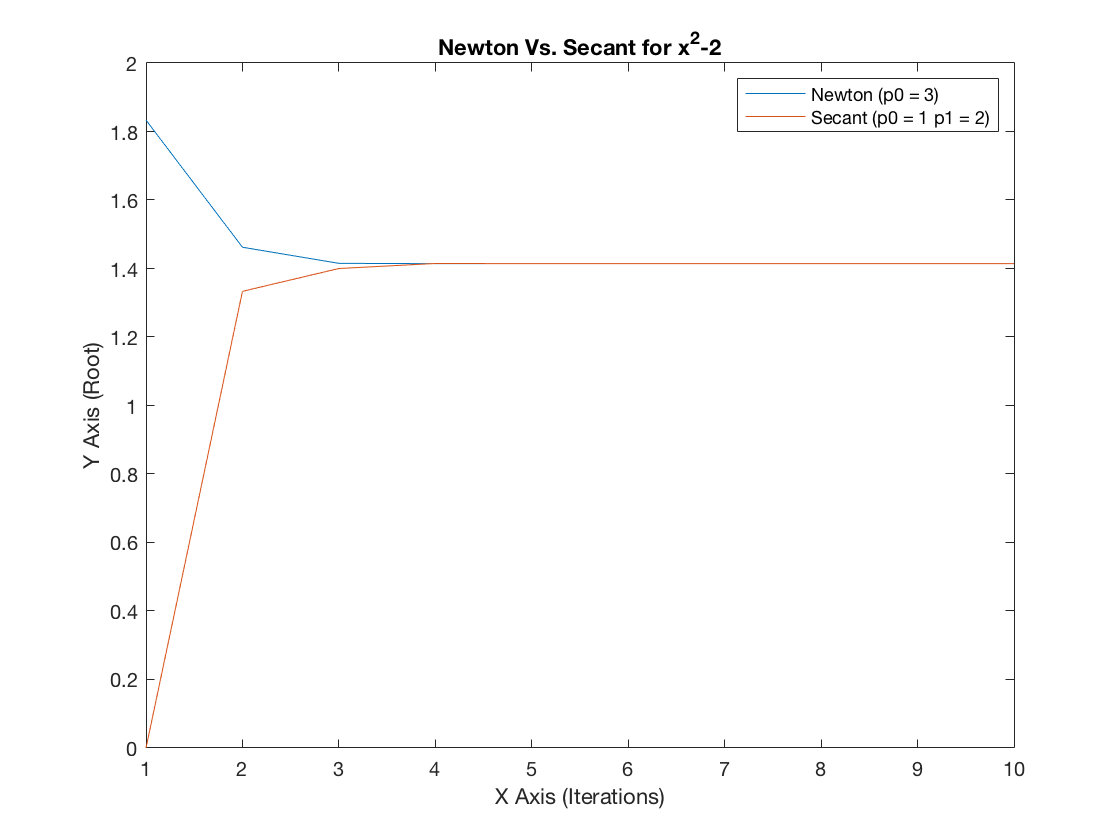

% x = linspace(0,1.5,10)
plot(g1)
hold on
plot(g2)
hold off
title('Newton Vs. Secant for x^2-2');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 3)','Secant (p0 = 1 p1 = 2)');

% g2 = secant(f,1,2,eps(),50);

%Number 3b
syms x
f = @(x) tanh(x);
df = diff(f(x));
if isempty(symvar(df))
  fPrime = str2func(['@(x) repmat(', char(df), ', size(x))'])
else
  fPrime = matlabFunction(df);
end
%Anything higher than 1.08 will give errors
g1 = newtones(f,fPrime,1.08,eps(),9);

The Procedure was sucessful. p is: 0


g2 = secant(f,-1,2,eps(),9);

The procedure was successful, p is: 0

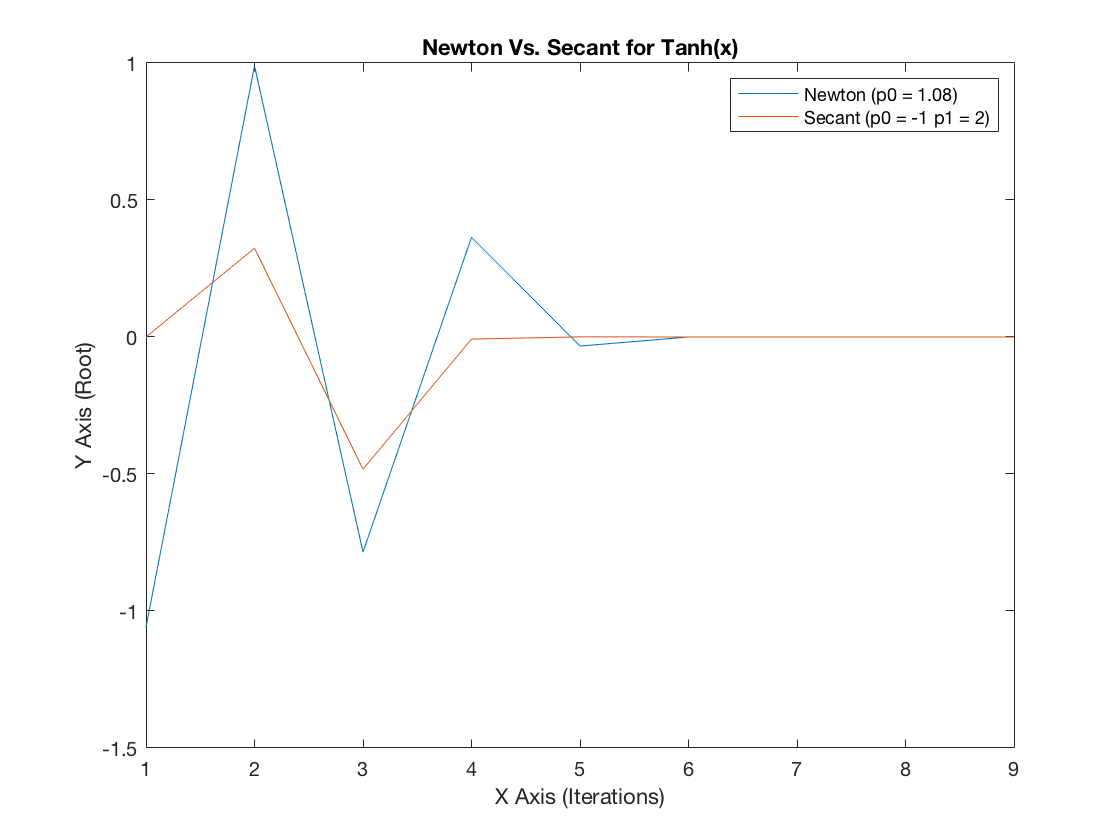

% x = linspace(0,2,9)
plot(g1)
hold on
plot(g2)
hold off
title('Newton Vs. Secant for Tanh(x)');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 1.08)','Secant (p0 = -1 p1 = 2)');

%Number 3c
f = @(x) (x^3-2*x+2);
df = diff(f(x));
if isempty(symvar(df))
  fPrime = str2func(['@(x) repmat(', char(df), ', size(x))'])
else
  fPrime = matlabFunction(df);
end
%When p0 = 0 or 1 in Newtones, it oscilates between 0 and 1
g1 = newtones(f,fPrime,2,eps(),50);

The Procedure was sucessful. p is: -1.7693


g2 = secant(f,-2,2,eps(),50);

The procedure was successful, p is: -1.7693

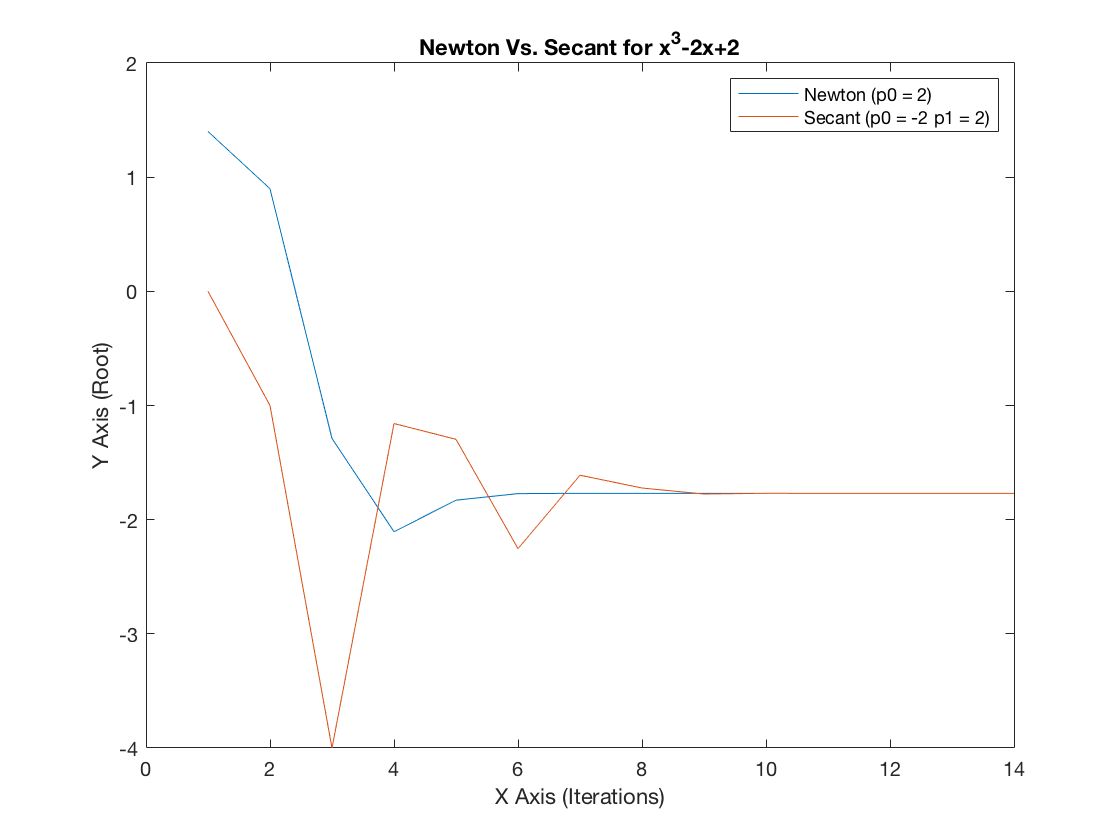

plot(g1)
hold on
plot(g2)
hold off
title('Newton Vs. Secant for x^3-2x+2');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 2)','Secant (p0 = -2 p1 = 2)');

%Number 3d
syms x
f = @(x) nthroot(x,3);
df = diff(f(x));

Error using nthroot (line 16)
Both X and N must be real.

Error in Worksheet 5>@(x)nthroot(x,3)

if isempty(symvar(df))
  fPrime = str2func(['@(x) repmat(', char(df), ', size(x))'])
else
  fPrime = matlabFunction(df);
end
g1 = newtones(f,fPrime,2,eps(),50);
g2 = secant(f,-2,2,eps(),50);
plot(g1)
hold on
plot(g2)
hold off
title('Newton Vs. Secant for x^3-2x+2');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 2)','Secant (p0 = -2 p1 = 2)');

function p = newtones(f,fPrime,p0,tol,maxits)
format long;
    i = 1;
    while (i <= maxits)
        p = p0-f(p0)/fPrime(p0);
        if (abs(p-p0) < tol)
            fprintf("The Procedure was sucessful. p is: " + p + "\n");
            g(i) = p;
            break;
        end
        g(i) = p;
%         fprintf("The current value at p is: " + p +  " iteration " + i +"\n");
        i = i+1;
        p0 = p;
    end 
    p = g;
end

function p = secant(f, p0, p1, tol, maxits)
format long;
    i = 2;
    q0 = f(p0);
    q1 = f(p1);
    while (i <= maxits)
        p = p1-(q1*(p1-p0))/(q1-q0);
        if (abs(p-p1) < tol)
            fprintf("The procedure was successful, p is: " + p);
            g(i) = p;
            break;
        end
%         fprintf("We are on iteration " + i + "\n");
        g(i) = p;
        i = i+1;
        p0 = p1;
        q0 = q1;
        p1 = p;
        q1 = f(p);
        if i > maxits
            fprintf("The output failed, we need more than " + i +" iterations");
        end
    end
    p = g;
end